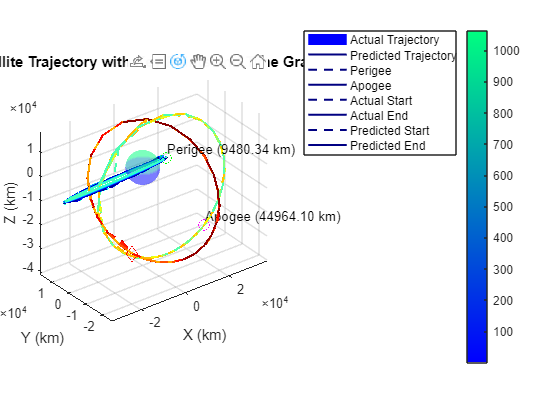

% Load the CSV file
data = readtable('satellite_trajectory_data.csv');

% Extract the relevant columns
sat_id = data.sat_id;
x_actual = data.x_actual;
y_actual = data.y_actual;
z_actual = data.z_actual;
x_predicted = data.x_predicted;
y_predicted = data.y_predicted;
z_predicted = data.z_predicted;

figure;

% Plot Earth
[xEarth, yEarth, zEarth] = sphere(50);
radiusEarth = 6378; % Earth's radius in km
surf(xEarth * radiusEarth, yEarth * radiusEarth, zEarth * radiusEarth, ...
    'EdgeColor', 'none', 'FaceAlpha', 0.3);
colormap winter;
hold on;

% Plot actual trajectory
num_points = length(x_actual);
cmap = jet(num_points); % Color gradient for time progression

for i = 1:num_points-1
    % Plot actual trajectory with color gradient
    plot3(x_actual(i:i+1), y_actual(i:i+1), z_actual(i:i+1), '-', 'Color', cmap(i, :), 'LineWidth', 1.5);
    
    % Plot predicted trajectory with color gradient
    plot3(x_predicted(i:i+1), y_predicted(i:i+1), z_predicted(i:i+1), '--', 'Color', cmap(i, :), 'LineWidth', 1.5);
end

% Calculate distances for actual trajectory
distance_actual = sqrt(x_actual.^2 + y_actual.^2 + z_actual.^2);
[perigee_distance, perigee_idx] = min(distance_actual);
[apogee_distance, apogee_idx] = max(distance_actual);

% Mark key points for actual trajectory
plot3(x_actual(perigee_idx), y_actual(perigee_idx), z_actual(perigee_idx), 'go', 'MarkerSize', 8, 'DisplayName', 'Perigee');
plot3(x_actual(apogee_idx), y_actual(apogee_idx), z_actual(apogee_idx), 'mo', 'MarkerSize', 8, 'DisplayName', 'Apogee');
plot3(x_actual(1), y_actual(1), z_actual(1), 'bs', 'MarkerSize', 8, 'DisplayName', 'Actual Start');
plot3(x_actual(end), y_actual(end), z_actual(end), 'bd', 'MarkerSize', 8, 'DisplayName', 'Actual End');

% Mark key points for predicted trajectory
plot3(x_predicted(1), y_predicted(1), z_predicted(1), 'rs', 'MarkerSize', 8, 'DisplayName', 'Predicted Start');
plot3(x_predicted(end), y_predicted(end), z_predicted(end), 'rd', 'MarkerSize', 8, 'DisplayName', 'Predicted End');

% Add legend and annotations
legend('Actual Trajectory', 'Predicted Trajectory', 'Perigee', 'Apogee', 'Actual Start', 'Actual End', 'Predicted Start', 'Predicted End');
text(x_actual(perigee_idx), y_actual(perigee_idx), z_actual(perigee_idx), sprintf('Perigee (%.2f km)', perigee_distance), 'VerticalAlignment', 'bottom');
text(x_actual(apogee_idx), y_actual(apogee_idx), z_actual(apogee_idx), sprintf('Apogee (%.2f km)', apogee_distance), 'VerticalAlignment', 'bottom');

% Axis labels and grid
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
title('Satellite Trajectory with Key Points and Time Gradient');
grid on;
axis equal;
colorbar;
caxis([1 num_points]);
rotate3d on;


% Convert to Geographic Coordinates for KML Export
R_earth = 6378; % Earth's radius in kilometers

% Convert actual trajectory
longitude_actual = atan2d(y_actual, x_actual); % Longitude in degrees
latitude_actual = asind(z_actual ./ sqrt(x_actual.^2 + y_actual.^2 + z_actual.^2)); % Latitude in degrees
altitude_actual = sqrt(x_actual.^2 + y_actual.^2 + z_actual.^2) - R_earth; % Altitude in km

% Convert predicted trajectory
longitude_predicted = atan2d(y_predicted, x_predicted); % Longitude in degrees
latitude_predicted = asind(z_predicted ./ sqrt(x_predicted.^2 + y_predicted.^2 + z_predicted.^2)); % Latitude in degrees
altitude_predicted = sqrt(x_predicted.^2 + y_predicted.^2 + z_predicted.^2) - R_earth; % Altitude in km

% Export actual trajectory to KML
kmlwrite('actual_trajectory.kml', latitude_actual, longitude_actual, altitude_actual, ...
    'Color', 'blue', 'LineWidth', 1.5);

% Export predicted trajectory to KML
kmlwrite('predicted_trajectory.kml', latitude_predicted, longitude_predicted, altitude_predicted, ...
    'Color', 'red', 'LineWidth', 1.5);

% Export combined trajectories to KML
kmlwrite('combined_trajectory.kml', ...
    [latitude_actual; latitude_predicted], ...
    [longitude_actual; longitude_predicted], ...
    [altitude_actual; altitude_predicted], ...
    'Color', 'green', 'LineWidth', 2);
